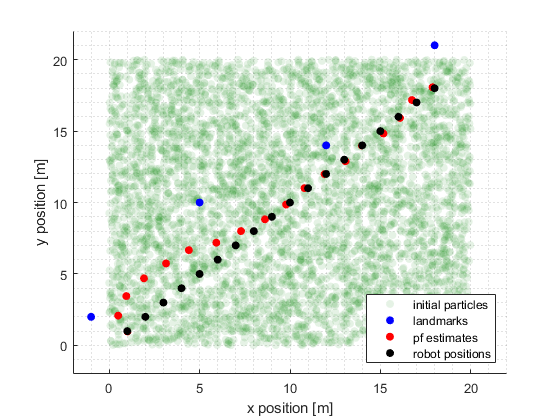

clear variables; close all;clc

% unscented kalman filter example 6
% tracking of a robot
% states = (position x, position y, orientation theta) = (x, y, theta)'
% control inputs = (commanded velocity, steering angle) =  (v, alpha)'

addpath('../utilities');

% time step [s]
dt = 1;

% number of particles
N = 5000;

% number of input commands
n = 18;

% landmarks information
% landmarks = [5 10; 10 5; 15 15; 20 5; 0 30; 50 30; 40 10]';
landmarks = [-1 2; 5 10; 12 14; 18 21]';

% dimensions
dim_x = 3;
dim_z = 2 * size(landmarks, 2);
dim_u = 2;

% input commands information
% u = ones(dim_u, n);
% u(:, 1:100) = u(:, 1:100).*[1.1 0.01]';
% u(:, 101:500) = u(:, 101:500).*[1.1 -0.01]';
% u(:, 501:600) = u(:, 501:600).*[1.1 0.05]';
commands = ones(dim_u, n).*[1.414, 0]';

% robot information
wheelbase = 0.5;
robot_pos = [0, 0, pi/4]';

% sensor noise std (range, bearing)
std_R = [0.1, 0];

% process noise std
std_Q = [0.05, 0.2];

% data structures
track = zeros(dim_x, n);
x_posterior = zeros(dim_x, n);
P_posterior = cell(1, n);
part_prior = cell(1, n);
part_posterior = cell(1, n);

neff = @(weights) 1/vecnorm(weights)^2;
all_close = @(a, b, rtol, atol) assert(all(abs(a - b) <= (atol + rtol * abs(b))));
 
% particles and weights
particles = uniform_particles(N, [0 20; 0 20; 0  6.28]);
particles(3, :) = mod(particles(3, :), 2*pi);
weights = ones(N, 1) / N;

% saving
part_init = particles;

% filtering
for ii = 1:n
    u = commands(:, ii);
    % simulate new robot position (x, y, theta)
    robot_pos = robot_move(robot_pos, u, dt, wheelbase);
        
    % build observations/measures
    z = robot_measure(robot_pos, landmarks, std_R(1), std_R(2), dim_z);
    
    % only range
    z = z(1:2:end);
    
    % predict robot heading orientation and position
    distance = u(1) * dt + randn(1, N) * std_Q(1);
    particles(3, :) = particles(3, :) + u(2) + randn(1, N) * std_Q(2);
    particles(3, :) = mod(particles(3, :), 2*pi);
    particles(1, :) = particles(1, :) + cos(particles(3, :)) .* distance;
    particles(2, :) = particles(2, :) + sin(particles(3, :)) .* distance;
    
    part_prior{ii} = particles;
    
    % update
    for jj = 1:size(landmarks, 2)
        dist = vecnorm(particles(1:2, :) - landmarks(:, jj));
        weights = weights .* normpdf(z(jj), dist, std_R(1))';
    end
    % round-off errors
    weights = weights + 1e-300;
    weights = weights / sum(weights);
       
    % resample
    if neff(weights) < (0.5 * N)
        
        % systematic resample: make N subdivisions, choose positions with a consistent random offset
        positions = ((0:N-1) + rand()) / N;
        indexes = zeros(N, 1);
        cumulative_sum = cumsum(weights);
        i = 1;
        j = 1;
        while i <= N
            if positions(i) < cumulative_sum(j)
                indexes(i) = j;
                i = i + 1;
            else
                j = j + 1;
            end
        end
        
        % resample from index
        particles(:) = particles(:, indexes);
        weights(:) = weights(indexes);
%         all_close(weights, 1/N, 1e-5, 1e-8);
        weights(:) = 1 / N;
    end
        
    % estimate
%         particles = gaussian_particles(N, [1 2 3]', [2 1 3]');
%         weights = ones(N, 1) * 0.25;
%         weights = weights / sum(weights);
    x = particles(1:3, :) * weights;
    pos_var = (particles(1:3, :) - x).^2 * weights;
    
    % saving
    track(:, ii) = robot_pos;
    x_posterior(:, ii) = x;
    P_posterior{ii} = pos_var;
    part_posterior{ii} = particles;
end

figure
hold on; grid minor;
scatter(part_init(1, :), part_init(2, :), 36, [0 0.5 0], 'filled', 'MarkerFaceAlpha', 0.1)
scatter(landmarks(1, :), landmarks(2, :), 'b', 'filled');
scatter(x_posterior(1, :), x_posterior(2, :) ,'r', 'filled');
scatter(track(1, :), track(2, :), 'k', 'filled', 'LineWidth', 2);
xlabel('x position [m]');
ylabel('y position [m]')
xlim([-2 22])
ylim([-2 22])
legend('initial particles' , 'landmarks', 'pf estimates', 'robot positions', 'location', 'southeast')

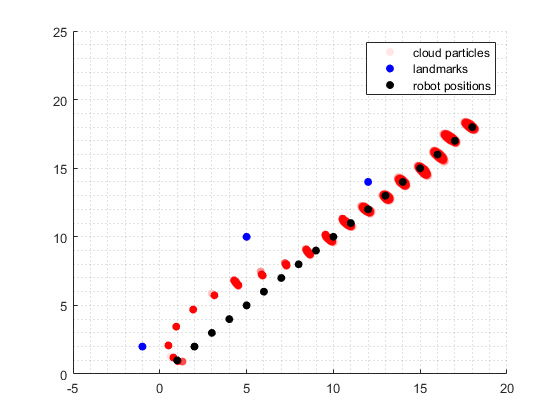

figure
hold on; grid minor;
p = part_posterior{1};
h1 = scatter(p(1, :), p(2, :), 'r', 'filled', 'MarkerFaceAlpha', 0.1);
for ii = 2:n
    p = part_posterior{ii};
    scatter(p(1, :), p(2, :), 'r', 'filled', 'MarkerFaceAlpha', 0.1);
end
h2 = scatter(landmarks(1, :), landmarks(2, :), 'b', 'filled');
h3 = scatter(track(1, :), track(2, :), 'k', 'filled', 'LineWidth', 2);
legend([h1 h2 h3], {'cloud particles', 'landmarks', 'robot positions'})